% Define a known precision matrix (inverse covariance) with a known sparsity pattern
% 5x5 precision matrix
true_precision = [ 1.0, -0.5,  0.0,  0.0,  0.0;
                  -0.5,  1.0, -0.4,  0.0,  0.0;
                   0.0, -0.4,  1.0, -0.3,  0.0;
                   0.0,  0.0, -0.3,  1.0, -0.2;
                   0.0,  0.0,  0.0, -0.2,  1.0];
               
% Make sure the matrix is symmetric
true_precision = (true_precision + true_precision') / 2;

% Check that true_precision is positive definite
eigvals = eig(true_precision);
if any(eigvals <= 0)
    error('Precision matrix is not positive definite');
end

% Compute the true covariance matrix as the inverse of the precision matrix
true_covariance = inv(true_precision);

% Number of samples to generate
n_samples = 1000;

% Generate data from a multivariate normal distribution
rng(0);  % Set random seed for reproducibility
data = mvnrnd(zeros(1, 5), true_covariance, n_samples);

% Define the sample size
sampleSize = 10;

% Calculate the number of full samples that fit
numFullSamples = floor(size(data,1) / sampleSize);

% Extract only the data that fits into full samples
sampledData = data(1:numFullSamples * sampleSize,:);

% Reshape into samples (optional for viewing as a matrix)
samples = reshape(sampledData', sampleSize,size(data,2), numFullSamples); % Now: [timesteps, variables, segments]


S = cov(data)

% Set regularization parameter for sparsity
lambda = 0.2;

enfoece_psd = false
% Initial guess: use only upper triangular elements
Theta0 = eye(size(S, 1));
% Call the custom Graphical Lasso fitting function with Lasso penalty
Theta_estimated = fitGraphicalLasso( Theta0, S,lambda,enfoece_psd);

% Display the result
disp('Optimal Precision Matrix (Theta):');
disp(Theta_estimated);

% Define a threshold for near-zero values to identify sparsity
threshold = 1e-4;

% Find non-zero structure in true and estimated precision matrices
true_sparsity_pattern = abs(true_precision) > threshold;
estimated_sparsity_pattern = abs(Theta_estimated) > threshold;

% Display the sparsity patterns
figure;
subplot(1, 2, 1);
imagesc(true_sparsity_pattern);
colorbar;
title('True Sparsity Pattern');
xlabel('Variable');
ylabel('Variable');

subplot(1, 2, 2);
imagesc(estimated_sparsity_pattern);
colorbar;
title('Estimated Sparsity Pattern');
xlabel('Variable');
ylabel('Variable');

% Calculate the accuracy of the sparsity pattern
match_rate = sum(sum(true_sparsity_pattern == estimated_sparsity_pattern)) / numel(true_sparsity_pattern);
disp(['Sparsity Pattern Match Rate: ', num2str(match_rate * 100), '%']);

# Comapring LASSO Algorithims

% Define a known precision matrix (inverse covariance) with a known sparsity pattern
lowVariance = false
if lowVariance
    true_precision = [ 1.0, -0.5,  0.0,  0.0,  0.0;
                      -0.5,  1.0, -0.4,  0.0,  0.0;
                       0.0, -0.4,  1.0, -0.3,  0.0;
                       0.0,  0.0, -0.3,  1.0, -0.2;
                       0.0,  0.0,  0.0, -0.2,  1.0];
else
    true_precision = [ 10.0, -1.8, -1.5, -1.2, -0.9;
                  -1.8,  10.0, -1.6, -1.3, -1.0;
                  -1.5, -1.6,  10.0, -1.4, -1.1;
                  -1.2, -1.3, -1.4,  10.0, -1.2;
                  -0.9, -1.0, -1.1, -1.2,  10.0];
end

% Ensure the matrix is symmetric and positive definite
true_precision = (true_precision + true_precision') / 2;
eigvals = eig(true_precision);
if any(eigvals <= 0)
    error('Precision matrix is not positive definite');
end

% Compute the true covariance matrix as the inverse of the precision matrix
true_covariance = inv(true_precision);

% Number of samples to generate
n_samples = 10000;

% Generate data from a multivariate normal distribution
rng(0);  % Set random seed for reproducibility
data = mvnrnd(zeros(1, 5), true_covariance, n_samples);

plot(data)

% Define the sample size and reshape data into segments
% ============================================================================
sampleSize = 1000;  % Define sample size (number of time steps in each segment)
% ============================================================================
[numObservations, numVariables] = size(data);
numFullSamples = floor(numObservations / sampleSize);

% Extract only the data that fits into full samples
sampledData = data(1:numFullSamples * sampleSize, :);

% Reshape into samples with dimensions [sampleSize, numVariables, numFullSamples]
samples = reshape(sampledData, sampleSize, numVariables, numFullSamples);

plot(samples(:,:,1))

% Cosntraint to enforce PSD, not required
enforce_psd = false;
% Set regularization parameter for sparsity
lambda = 0.0;

## Graphical Lasso

samplesB = reshape(samples, size(samples,1) * size(samples,3), size(samples,2));
Sem = cov(samplesB);

% Initial guess: use only upper triangular elements
Theta0 = eye(size(S, 1));
% Call the custom Graphical Lasso fitting function with Lasso penalty
Theta_estimated = fitGraphicalLasso( Theta0, Sem,lambda,enforce_psd);

% Display the result
disp('GL: Optimal Precision Matrix (Theta):');
disp(Theta_estimated);

## Time Varying Graphical Lasso


% Calculate the empirical covariance matrices for each segment
S = zeros(numVariables, numVariables, numFullSamples);  % Initialize covariance matrix storage
for t = 1:numFullSamples
    S(:, :, t) = cov(squeeze(samples(:, :, t)));  % Calculate covariance for each segment
end


% Set initial precision matrices and regularization parameter
Theta0t = repmat(eye(size(S, 1)), 1, 1, numFullSamples);  % Initial guess as identity matrices
enforce_psd = false;  % Enforce positive semidefiniteness


% Call the fitTimeVaryingGraphicalLasso function
Theta_estimated_TVGL = fitTimeVaryingGraphicalLasso(Theta0t, S, lambda, numFullSamples,enforce_psd);

% Display results
disp('TVGL (No transion Penalty): Estimated precision matrices:');
disp(Theta_estimated_TVGL);

## Time Varying Graphical Lasso with Transition Penalty

beta = 12.5;
% Initial guess: use only upper triangular elements
%Theta0 = repmat(eye(size(S,1)), 1, 1, numFullSamples); 
% Call the custom Graphical Lasso fitting function with Lasso penalty
Theta_estimated_TVGL_TP= fitTimeVaryingGraphicalLassoSmoothing(Theta0t, S, lambda, beta, numFullSamples, enforce_psd);

% Display the result
disp('TVGL with Transition Penalty: Optimal Precision Matrix (Theta):');
disp(Theta_estimated_TVGL_TP);


% Add temporal smoothing penalty between consecutive precision matrices
f = zeros(1,size(Theta_estimated_TVGL,3)-1);
for t = 2:1:size(Theta_estimated_TVGL,3)
    diff_matrix = Theta_estimated_TVGL(:, :, t) - Theta_estimated_TVGL(:, :, t-1);
    p = norm(diff_matrix, 'fro')^2; % Normalized penalty
    f(t) = p;
end

g = zeros(1,size(Theta_estimated_TVGL_TP,3)-1);
for t = 2:1:size(Theta_estimated_TVGL_TP,3)
    diff_matrix = Theta_estimated_TVGL_TP(:, :, t) - Theta_estimated_TVGL_TP(:, :, t-1);
    q = norm(diff_matrix, 'fro')^2; % Normalized penalty
    g(t) = q;
end

figure
plot(f)
hold on
plot(g)
hold off




Betas = 0:0.1:1;
g = zeros(length(Betas),size(Theta_estimated_TVGL_TP,3)-1);
for i = 1:1:length(Betas)
    beta = Betas(i);
    % Initial guess: use only upper triangular elements
    Theta0 = repmat(eye(size(S,1)), 1, 1, numFullSamples); 
    % Call the custom Graphical Lasso fitting function with Lasso penalty
    Theta_estimated_TVGL_TP= fitTimeVaryingGraphicalLassoSmoothing(Theta0, S, lambda, beta, numFullSamples, enforce_psd);
    
   
    for t = 2:1:size(Theta_estimated_TVGL_TP,3)
        diff_matrix = Theta_estimated_TVGL_TP(:, :, t) - Theta_estimated_TVGL_TP(:, :, t-1);
        q = norm(diff_matrix, 'fro')^2; % Normalized penalty
        g(i,t) = q;
    end

end

function isPositiveDef(X)
    % Check that true_precision is positive definite
    eigvals = eig(X);
    if any(eigvals <= 0)
        disp('matrix is not positive definite');
    end
end

% Define parameters
mean_value = 0;       % Desired mean
std_dev = 10;          % Desired standard deviation
n = 10;               % Size of the matrix (n x n)

% Generate random numbers from the specified normal distribution
matrix = mean_value + std_dev * randn(n, n);
matrix = (matrix*matrix')/2




Precision = inv(matrix)


% Check that true_precision is positive definite
eigvals = eig(Precision)
if any(eigvals <= 0)
    error('Precision matrix is not positive definite');
end

% Display the result
disp(matrix);






function [pre_matrix, cov_matrix] = dispersion_matrix(n,mean_value,std_dev)
    % Generate random numbers from the specified normal distribution
    matrix = mean_value + std_dev * randn(n, n);
    
    % Construct the positive definite covariance matrix
    cov_matrix = matrix' * matrix;
    
    % Scale the matrix to have variances close to 1 on the diagonal (optional)
    cov_matrix = cov_matrix ./ max(abs(diag(cov_matrix)));
    isPositiveDef(cov_matrix)
    
    % precision matrix
    pre_matrix = inv(cov_matrix);
    isPositiveDef(pre_matrix)
end

function [pre_tensor, cov_tensor] = dispersion_tensor(sections,n,mean_value,std_dev)
    
    pre_tensor = zeros(n,n,sections);
    cov_tensor = zeros(n,n,sections);
    
    for s = 1:1:sections
        [pre_matrix, cov_matrix] = dispersion_matrix(n,mean_value,std_dev(s));
        pre_tensor(:,:,s) = pre_matrix;
        cov_tensor(:,:,s) = cov_matrix;
    end

end


sections = 10;

mean_value = 0;       % Desired mean
std_dev = randi(20,[1,sections])         % Desired standard deviation

std_dev =     15     2    12    18     9    14     7    13     6    16


n = 5;               % Size of the matrix (n x n)

[pre_tensor, cov_tensor] = dispersion_tensor(sections,n,mean_value,std_dev);


function data = GenerateRandomData(num_variables,true_covariance,n_samples,sections)
    
    data = zeros(n_samples*sections,num_variables);
    Start = 1;
    End = n_samples;
    for s = 1:1:sections
    
        rng(0);  % Set random seed for reproducibility
        data(Start:End,:) = mvnrnd(zeros(1, num_variables), true_covariance(:,:,s), n_samples);
        Start = Start + n_samples;
        End = End + n_samples;
    end

end


% Number of samples to generate
n_samples = 1000;
data = GenerateRandomData(n,cov_tensor,n_samples,sections)

data =     0.2013    0.4499   -0.0266    0.6070    0.1255
    0.6868   -1.2546    1.2692    0.3493   -0.0843
   -0.8459    0.3942    0.0545   -0.4974    0.3460
    0.3229   -0.9256    0.3590    0.5921   -0.0335
    0.1194    0.4324   -0.2213   -0.2472   -0.1559
   -0.4897   -0.2853    0.3106   -0.3068    0.2323
   -0.1624   -0.8519    0.3981   -0.8457   -0.0768
    0.1283    0.4029    0.3318    0.2914    0.1049
    1.3401   -1.6187    0.8109   -0.2492   -0.7152
    1.0371   -0.6048    0.7561    0.0200   -0.4506


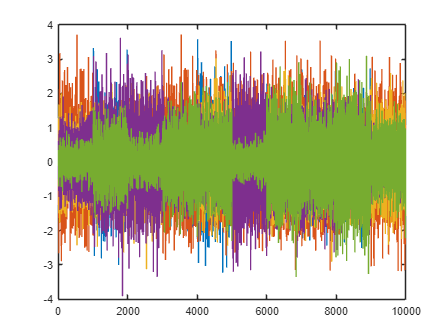



plot(data)